% ----------------- Kommentarer ----------------- 
% För en snabb körning så är det bara att köra Run, n=500 då.
% För att köra detta för upp till n=5000 så sätt shorterRun = 0.
% till bara "SIZE = length(n);"
% 
% -------- OBS!!! --------  
% KÖRNINGAR FÖR n = 5000x5000 FINNS REDAN SPARADE I GVL_time_results_n5000.mat
% 
% FIGURER FINNS REDAN SPARADE I GVL_n_5000x5000.fig OCH
% GVL_n_5000x5000_SEMILOGY.fig

% -------- OBS #2! --------  
% Resultatet i form av grafer och vektorer finns allra längst ned.

clear
clc
shorterRun = 4;
n = [10, 100, 500, 1000, 2000, 3000, 4000];
SIZE = length(n) - shorterRun;

## GVL Algorithm 1.1.5

elapsedTime115 = zeros(SIZE,1);
for i = 1:SIZE
    elapsedTime115(i) = GVL_1_1_5(n(i), n(i), n(i));
end

% figure
% plot(elapsedTime115)
% title('Matrix multiplication')
% xlabel('x=1,2,3,4,5,6,7 motsvarar matrisstorleken n = 10, 100, 500, 1000, 2000, 3000, 4000')
% ylabel('Tid i sekunder')
% hold on

## GVL Algorithm 1.1.6

elapsedTime116 = zeros(SIZE,1);
for i = 1:SIZE
    elapsedTime116(i) = GVL_1_1_6(n(i), n(i), n(i));
end

% figure
% plot(elapsedTime116)
% title('Dot Product Matrix Multiplication')
% xlabel('x=1,2,3,4,5,6,7 motsvarar matrisstorleken n = 10, 100, 500, 1000, 2000, 3000, 4000')
% ylabel('Tid i sekunder')

## GVL Algorithm 1.1.7

elapsedTime117 = zeros(SIZE,1);
for i = 1:SIZE
    elapsedTime117(i) = GVL_1_1_7(n(i), n(i), n(i));
end

% figure
% plot(elapsedTime117)
% title('Saxpy Matrix Multiplication')
% xlabel('x=1,2,3,4,5,6,7 motsvarar matrisstorleken n = 10, 100, 500, 1000, 2000, 3000, 4000')
% ylabel('Tid i sekunder')

## GVL Algorithm 1.1.8

elapsedTime118 = zeros(SIZE,1);
for i = 1:SIZE
    elapsedTime118(i) = GVL_1_1_8(n(i), n(i), n(i));
end

% figure
% plot(elapsedTime118)
% title('Outer Product Matrix Multiplication')
% xlabel('x=1,2,3,4,5,6,7... motsvarar matrisstorleken n = 10, 100, 500, 1000:1000:10000')
% ylabel('Tid i sekunder')

## Results

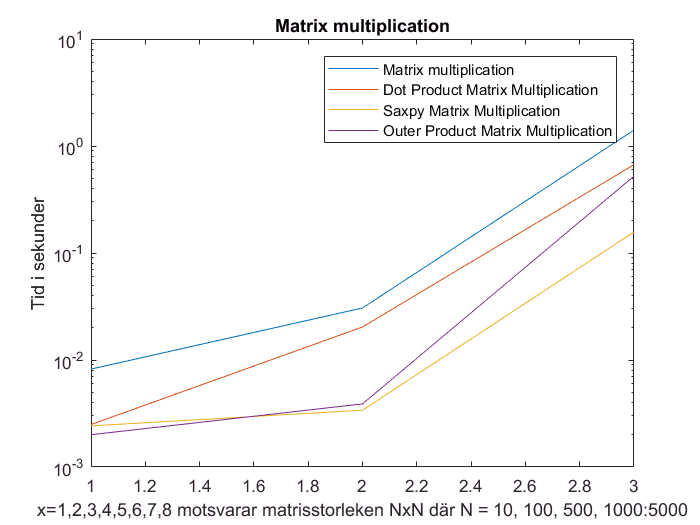

semilogy(elapsedTime115, 'DisplayName', 'Matrix multiplication')
hold on

semilogy(elapsedTime116, 'DisplayName', 'Dot Product Matrix Multiplication')
semilogy(elapsedTime117, 'DisplayName', 'Saxpy Matrix Multiplication')
semilogy(elapsedTime118, 'DisplayName', 'Outer Product Matrix Multiplication')

title('Matrix multiplication')
xlabel('x=1,2,3,4,5,6,7,8 motsvarar matrisstorleken NxN där N = 10, 100, 500, 1000:5000')
ylabel('Tid i sekunder')

legend('show')

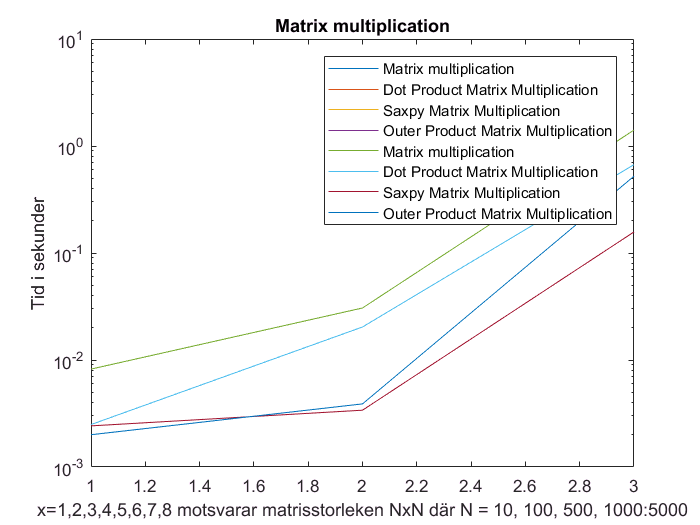

plot(elapsedTime115, 'DisplayName', 'Matrix multiplication')
hold on

plot(elapsedTime116, 'DisplayName', 'Dot Product Matrix Multiplication')
plot(elapsedTime117, 'DisplayName', 'Saxpy Matrix Multiplication')
plot(elapsedTime118, 'DisplayName', 'Outer Product Matrix Multiplication')

title('Matrix multiplication')
xlabel('x=1,2,3,4,5,6,7,8 motsvarar matrisstorleken NxN där N = 10, 100, 500, 1000:5000')
ylabel('Tid i sekunder')


legend('show')